Transfer function decleration

num = [1.6 4];
den = [1 10.3 34.5 37.3];
sys = tf(num, den)

sys =
 
            1.6 s + 4
  ------------------------------
  s^3 + 10.3 s^2 + 34.5 s + 37.3
 
Continuous-time transfer function.



Finding zeros and poles

[zeros1, poles] = tf2zp(num,den)

zeros1 = -2.5000

poles =    -4.2044
   -3.6939
   -2.4017


Stability Checking

stability = isstable(sys)

stability = logical
   1


Minimum Phase checking

min_phase = isminphase(num, den)

min_phase = logical
   0


State space form

[A, B, C, D] = tf2ss(num, den)

A =   -10.3000  -34.5000  -37.3000
    1.0000         0         0
         0    1.0000         0


B =      1
     0
     0


C =          0    1.6000    4.0000


D = 0

state_space = ss(A, B, C, D);

Controllability Checking

ctrl_matrix = ctrb(A, B);
rank(ctrl_matrix)

ans = 3

Observability Checking

obs_matrix = obsv(A, C);
rank(obs_matrix)

ans = 3

Minimal form of system

minimal_form = minreal(state_space)

minimal_form =
 
  A = 
          x1     x2     x3
   x1  -10.3  -34.5  -37.3
   x2      1      0      0
   x3      0      1      0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
 
  C = 
        x1   x2   x3
   y1    0  1.6    4
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



Step response

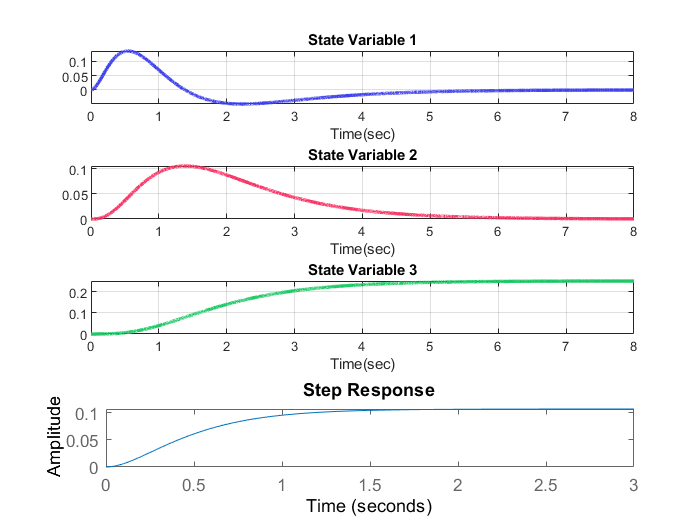

step(state_space)

unit feedback

closedloop = feedback(sys, 1);
[zeros2, poles2] = tf2zp(closedloop.Numerator{1} ,closedloop.Denominator{1})

zeros2 = -2.5000

poles2 =   -3.9285 + 1.2133i
  -3.9285 - 1.2133i
  -2.4431 + 0.0000i


State Feedback

p = [-1 -2 -3]

p =     -1    -2    -3


k = place(A, B, p)

k =    -4.3000  -23.5000  -31.3000


pole_closed_loop = eig(A - B*k)

pole_closed_loop =    -3.0000
   -2.0000
   -1.0000


State feedback design

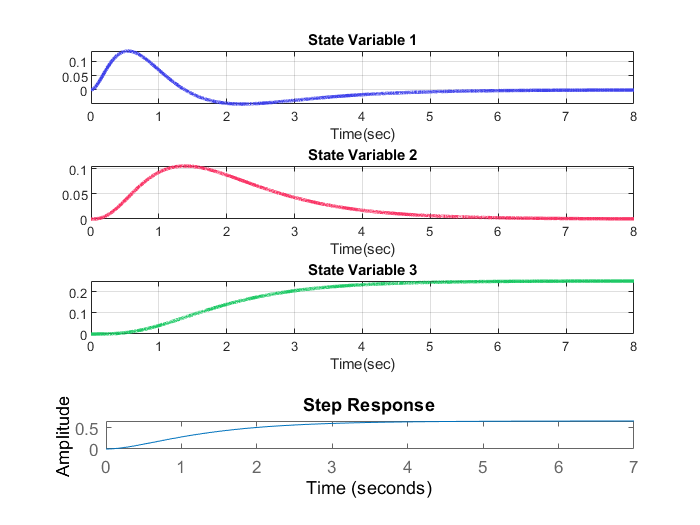

state_space_cl = ss(A-B*k, B, C, D);
step(state_space_cl)

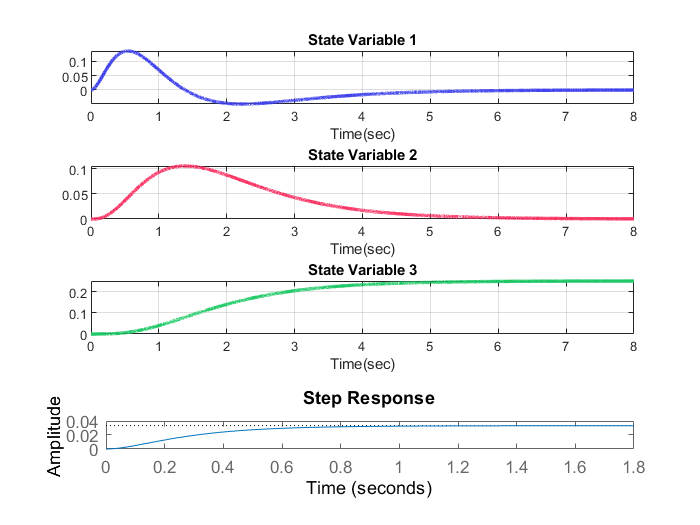

p2 = [-10 -5 -2.4];
k2 = place(A, B, p2);
state_space_cl2 = ss(A-B*k2, B, C, D);
step(state_space_cl2)

p3 = [-0.1 -0.2 -0.5];
k3 = place(A, B, p3)

k3 =    -9.5000  -34.3300  -37.2900


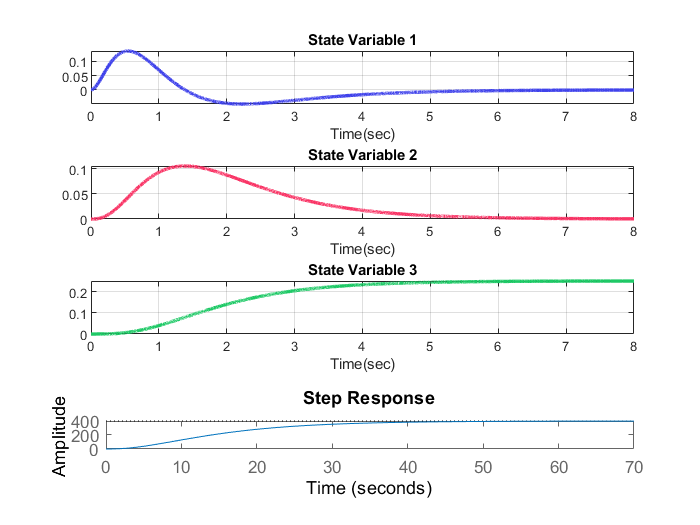

state_space_cl3 = ss(A-B*k3, B, C, D);
step(state_space_cl3)

Robust Tracking

A_new = [A zeros(3,1) ; -C zeros(1,1)];
B_new = [B;zeros(1,1)];
C_new = [C zeros(1,1)];
sys_robust = ss(A_new,B_new,C_new,D);
Controllability_new = ctrb(A_new,B_new)

Controllability_new =     1.0000  -10.3000   71.5900 -419.3270
         0    1.0000  -10.3000   71.5900
         0         0    1.0000  -10.3000
         0         0   -1.6000   12.4800


rank(Controllability_new)

ans = 4

integ_k = place(A_new,B_new,[-1 -2 -3 -4])

integ_k =    -0.3000    0.5000    3.1000   -6.0000


K1 = integ_k(:,1:3)

K1 =    -0.3000    0.5000    3.1000


K2 = -integ_k(:,4)

K2 = 6.0000

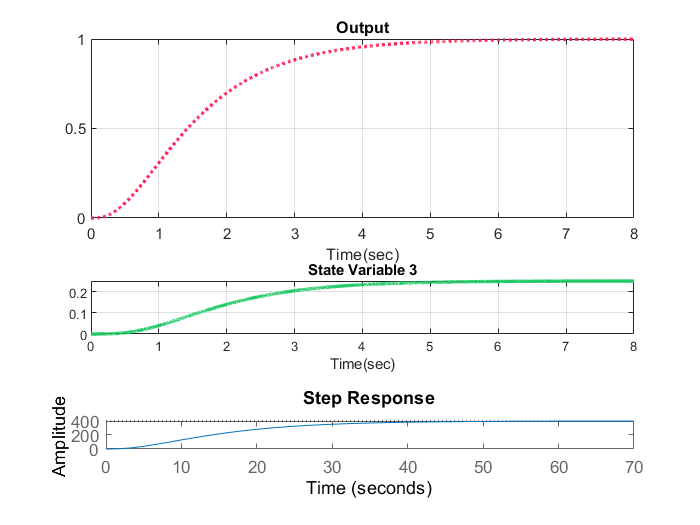

A_integ = [A-B*K1 B*K2;-C zeros(1,1)];
B_integ = [zeros(3,1);1];
integ_sys = ss(A_integ,B_integ,C_new,D);
x0_integ = [1 2 2 1]';
r = ones(1,10000);
t = linspace(0,8,10000);
[integ_y,~,x] = lsim(integ_sys,r,t,0*x0_integ);
control_signal_integ = K2*x(:,4)' - K1*x(:,1:3)';

% Plotting
subplot(2,1,1);
plot(t,integ_y, ':', 'Color', '#ff1852', 'linewidth', 2)
title('Output')
xlabel('Time(sec)')
grid on;

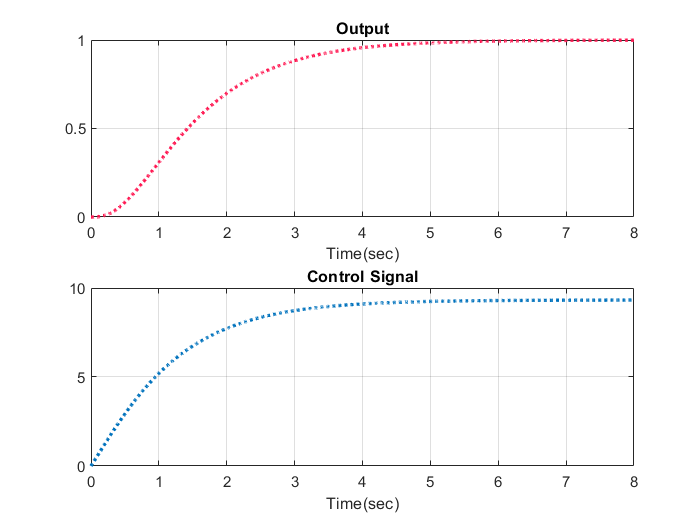


subplot(2,1,2);
plot(t, control_signal_integ, ':', 'LineWidth', 2);
title('Control Signal')
xlabel('Time(sec)')
grid on;

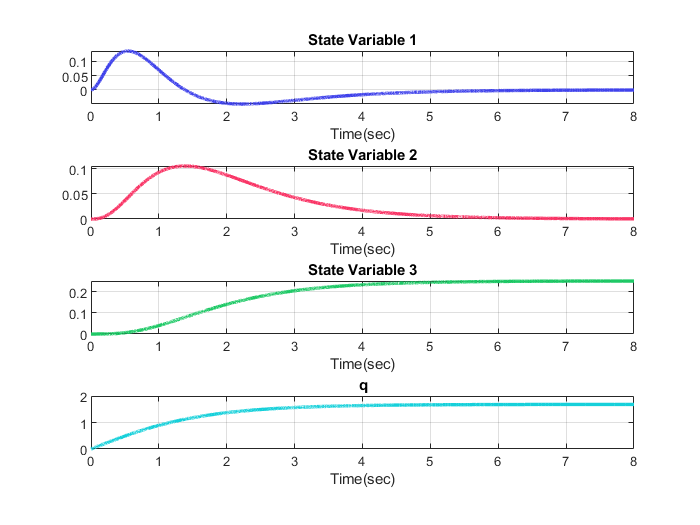


% State Variables
figure
subplot(4,1,1);
plot(t,x(:,1), 'Color', '#4043eb', 'linewidth', 2)
title('State Variable 1')
xlabel('Time(sec)')
grid on

subplot(4,1,2);
plot(t, x(:,2), 'Color', '#f93566', 'linewidth', 2)
title('State Variable 2')
xlabel('Time(sec)')
grid on

subplot(4,1,3);
plot(t, x(:,3), 'Color', '#1ec966', 'linewidth', 2)
title('State Variable 3')
xlabel('Time(sec)')
grid on

subplot(4,1,4);
plot(t, x(:,4), 'Color', '#16d0da', 'linewidth', 2)
title('q')
xlabel('Time(sec)')
grid on

Static Variable change effect on Robust tracking

A = A + [0 1 1 ;1 0 0 ;0 1 0];
B = B + [1; 1; 1];

Robust tracking

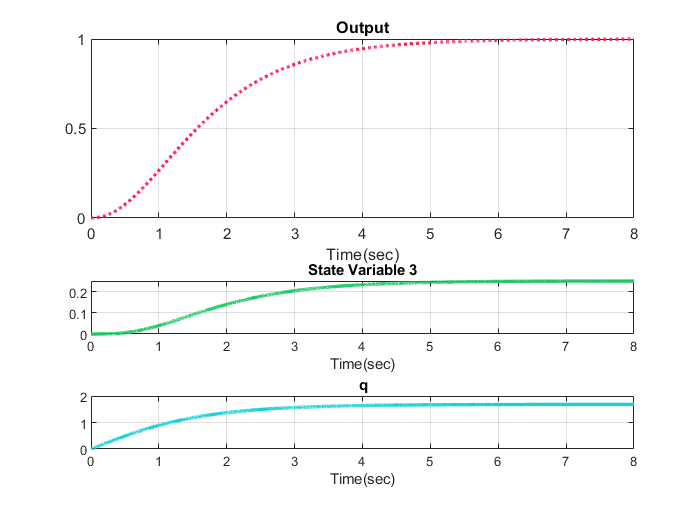

A_new = [A zeros(3,1) ; -C zeros(1,1)];
B_new = [B;zeros(1,1)];
C_new = [C zeros(1,1)];
sys_robust = ss(A_new,B_new,C_new,D);
Controllability_new = ctrb(A_new,B_new);
rank(Controllability_new);
integ_k = place(A_new,B_new,[-1 -2 -3 -4]);
K1 = integ_k(:,1:3);
K2 = -integ_k(:,4);
A_integ = [A-B*K1 B*K2;-C zeros(1,1)];
B_integ = [zeros(3,1);1];
integ_sys = ss(A_integ,B_integ,C_new,D);
x0_integ = [1 2 2 1]';
r = ones(1,10000);
t = linspace(0,8,10000);
[integ_y,~,x] = lsim(integ_sys,r,t,0*x0_integ);
control_signal_integ = K2*x(:,4)' - K1*x(:,1:3)';

% Plotting
subplot(2,1,1);
plot(t,integ_y, ':', 'Color', '#ff1852', 'linewidth', 2)
title('Output')
xlabel('Time(sec)')
grid on;

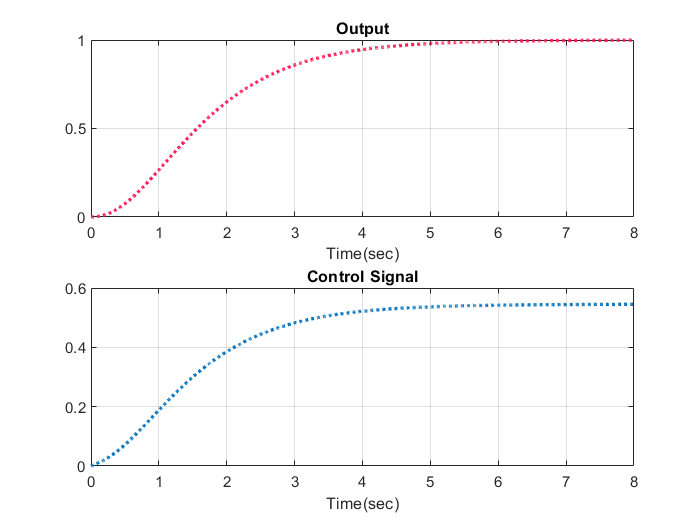


subplot(2,1,2);
plot(t, control_signal_integ, ':', 'LineWidth', 2);
title('Control Signal')
xlabel('Time(sec)')
grid on;

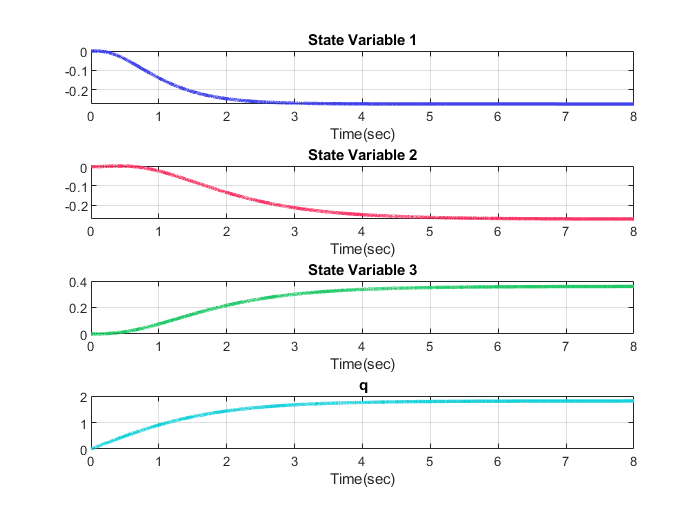

% State Variables
figure
subplot(4,1,1);
plot(t,x(:,1), 'Color', '#4043eb', 'linewidth', 2)
title('State Variable 1')
xlabel('Time(sec)')
grid on

subplot(4,1,2);
plot(t, x(:,2), 'Color', '#f93566', 'linewidth', 2)
title('State Variable 2')
xlabel('Time(sec)')
grid on

subplot(4,1,3);
plot(t, x(:,3), 'Color', '#1ec966', 'linewidth', 2)
title('State Variable 3')
xlabel('Time(sec)')
grid on

subplot(4,1,4);
plot(t, x(:,4), 'Color', '#16d0da', 'linewidth', 2)
title('q')
xlabel('Time(sec)')
grid on

%lilililill